# Iterative Rational Krylov Algorithm (IRKA-PH)

## Introduction

[Krylov subspace reduction methods](matlab: edit demo_arnoldiPH.mlx) provide a powerful framework for computationally feasible reduction of large-scale systems. They come, however, with a new challenge of finding suitable shifts $\sigma_k$ wich capture the most important features of the original systems well. 

One possible solution to this is the **Iterative Rational Krylov Algorithm (IRKA)** by Gugercin et al. [1]. As suggested by the name, it iteratively finds new shifts for Krylov-subspace reduction which optimize the $H_2$ error norm between the original and the reduced system. Thus, upon convergence of the algorithm, the reduced system 'optimally' represents the original system in some sense.

### The idea

In their paper [1], Beattie et al. show that any local minimizer $G_r$ (with some given reduced dimension $r$) of the $H_2$ optimization problem


$$\min_{G_r} || G(s) - G_r(s) ||_{H_2}$$


satisfies the following necessary optimality conditions (for simplicity we only consider SISO systems here):


$$G_r(-\tilde{\lambda}_i) = G(-\tilde{\lambda}_i) \quad and \quad G_r{\prime}(-\tilde{\lambda}_i) = G{\prime}(-\tilde{\lambda}_i), \quad i = 1, ..., r$$


where $\prime$ denotes the derivative w.r.t. $s$ and $\tilde{\lambda}_i$ are the *eigenvalues of the reduced system *$G_r$*. *

Since these eigenvalues are not known in advance, an iterative approach is chosen. In each iteration we determine a reduced order system $G_r$ (starting with some intial shifts). In the subsequent iteration, we assign  $\sigma_k = \tilde{\lambda}_k$ for reduction. When the algorithm converges, the two optimality conditions are fulfilled.

### IRKA-PH

The IRKA algorithm can easily be extended to **IRKA-PH**, i.e. IRKA for port-Hamiltonian systems, by using any of the measures which can be used for the Arnoldi algorith, see [Krylov subspace reduction methods](matlab: edit Structure_preserving_Krylov_subspace_reduction.mlx). For example, such structure preserving versions have been proposed by [2], [3].

Note, however, that due to the limitations on the choice of the reduction matrix $W$, one can generally not fulfill both necessary optimality conditions any more. IRKA-PH might thus *not be *$H_2$*-optimal*. It still gives good approximations in many use-cases.

## Toolbox Implementation

The MORpH toolbox provides an implementation of the IRKA-PH algorithm called *irkaPH*.

This algorithm is relatively easy to use and often provides reasonable results. You only need to pass the system to be reduced and the desired reduced order to the function.

In the background, *irkaPH* runs the IRKA iteration with calls to *arnoldiPH* for reduction. If you want to customize the algorithms behaviour you can specify initial shifts (and tangent directions for MIMO systems) and pass a structure with execution parameters.

The latter offers plenty of choices. In fact, you can even modify the parameters for the lower-level functions *arnoldiPH *and *structurePreservation*. Please refer to the functions' documentation for more details.

help irkaPH

## Examples

We will consider a mass-spring-damper system with the following architecture

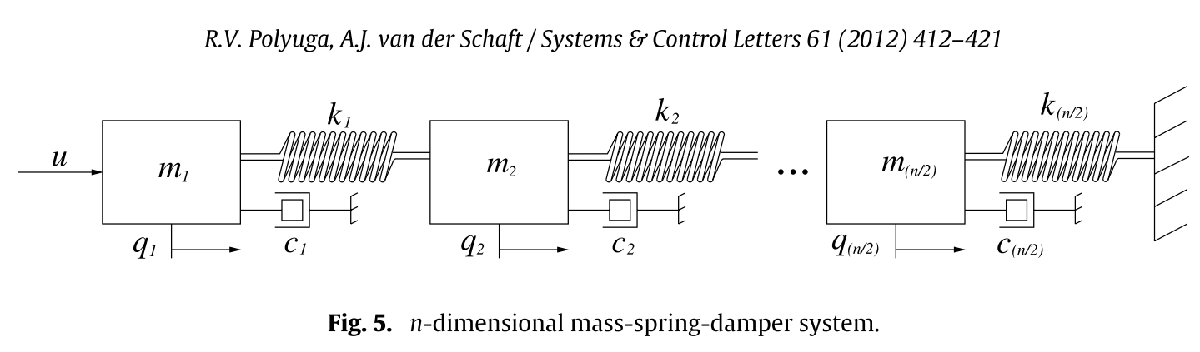

Image source: [4]

and $n = 100$, i.e. 50 masses ($m = 2$), 50 springs ($k = 1$), and 50 dampers ($d = 1$) .

sys = setup_MassSpringDamperSystem(100, 2, 1, 1, 'SISO')

### Simple reduction

Let us first keep things as simple as possible. We want to reduce the system to dimension $r = 20$. For this, we simply execute

sysr = irkaPH(sys, 20)

We see that the algorithm converged within only a few iterations.

For evaluation, we consider the $H_2$ error norm and have a look at the Bode plot:

error = norm(sys - sysr)
bode(sys, sysr)
legend("Original", "Reduced")

### Customization: Initial shifts

#### Custom shifts

Let us now customize the initial shifts. Let's say we prefer a combination of zeros and shifts at infinity for a start:

s0 = [zeros(1, 15), inf(1, 5)]

We provide this vector as input and run the algorithm

sysr_s0 = irkaPH(sys, s0)

The error norm now becomes

error_s0 = norm(sysr_s0 - sys)

In fact, the obtained system is pretty close to the previous system, as it is often (but not always) the case for irkaPH upon convergence.

difference_reduced = norm(sysr - sysr_s0)

#### Initialization strategies

Since finding initial shifts is often not required and tedious, *irkaPH* offers you a collection of different strategies which select initial shifts based on properties (e.g. eigenvalues) of the original system. You can pass a structure with execution parameters *.initShifts* which will be passed to the *initShifts *function.

help initShifts
Opts = struct();
Opts.initShifts = 'logarithmic';
sysr_log = irkaPH(sys, 20, Opts)

### Customization: Structure Preservation Strategy, Nested options

Similarly to *arnoldiPH*, you can use different structure preservation strategies, see *structurePreservation*:

help structurePreservation

To pass these arguments appropriately, use a **nested structure** as follows:

Opts.arnoldiPH.structurePreservation = 'QV';
sysr_QV = irkaPH(sys, 20, Opts)

Note that in this particular case (we use '*QV*'), the reduced system is in descriptor form.

### Customization: Other options

There are a lot more options which you can choose from. Please refer to the documentation of the respective (sub-) functions for more information.

## A closer look to the output

We tried to make our algorithm as easy to use as possible. For this, we kept most interfaces simple and hide possibly irrelevant information.

However, we also want to make the algorithm as transparent as possible. For this, we provide lots of optional, additional output.

### Console output

If you want to know more about what is going on, you can use the options struct with an entry .*verbose* set to true. This will print more information in every iteration. For even more output, you may set the same entry as nested option for *arnoldiPH* and the *phs class*.

For demonstration purposes, you may want to try the interactive mode (*.interactive*).

### Function output

When you run irkaPH, you can also obtain the matrices $V$ and $W$ used for projection, the final shifts '*s0*' (and tangent directions '*b*') as well as the number of LU decompositions required.

Opts = struct();
Opts.initShifts = 'eig_small';
Opts.arnoldiPH.structurePreservation = 'Cholesky+';
Opts.stopCrit = 'combAny';
Opts.tol = 1e-5;
[sysr, V, s0, b, W, nLU] = irkaPH(sys, 20, Opts)

### redSys information

The reduced system also provides some information which is stored alongside the system matrices.

The properties *method* and *parameters* keep track of the algorithm and options (including defaults) which were used for reduction. 

sysr.method
sysr.parameters

The property *info* tells you more about what happened during reduction

sysr.info
sysr.info.stopCritEvolution

## References

[1] Gugercin et al. (2008), $\mathcal{H}_2$ *Model Reduction for Large-scale Linear Dynamical Systems*, in SIAM Journal on Matrix Analysis and Applications 2008 (30).

[2] Gugercin et al. (2009),* Interpolation-based *$\mathcal{H}_2$* model reduction for port-Hamiltonian systems*, in Proceedings of the 48th IEEE Conference on Decision and Control (CDC) held jointly with 2009 28th Chinese Control Conference

[3] S. Gugercin, Rostyslav V. Polyuga, C. Beattie, and A. van der Schaft. Structure-preserving tangential interpolation for model reduction of port-Hamiltonian systems. *Automatica J. IFAC*, 48(9):1963–1974, 2012.

[4] R. V. Polyuga and A. van der Schaft. Effort- and flow-constraint reduction methods for structure-preserving model reduction of port-Hamiltonian systems. *Systems Control Letters*, 61(3):412–421, 2012.  

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Julius Durmann    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)